# kalman_filter_example.mlx

Copyright (C) 2022, Rodrigo Gonzalez, all rights reserved.

*This file is free software: you can re distribute it and/or modify it under the terms of the GNU Lesser General Public License (LGPL) version 3 as published by the Free Software Foundation. This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU Lesser General Public License for more details. You should have received a copy of the GNU Lesser General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.*

- Version: 001

- Date:    2022/06/13

- Author:  Rodrigo Gonzalez <rodralez@frm.utn.edu.ar>

- URL:     https://github.com/rodralez/control

- References:  

## **PHYSICAL SYSTEM**

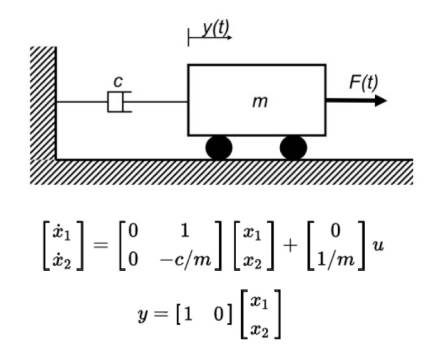

Where, 

- Mass, m = 1 kg. 

- Suspension spring coefficient, c = 1 N/m

- Mass position, x1.

- Mass velocity, x2.

- Input force, F(t) = 2 N

## **INIT**

clc
clear
close all

% COLORS
blue    = [0, 0.4470, 0.7410];
orange  = [0.8500, 0.3250, 0.0980];
green   = [0.4660, 0.6740, 0.1880];
yellow  = [0.9290, 0.6940, 0.1250];
grey    = ones(1,3) * 0.65;

## INPUT VARIABLES

% Time vector, from 0 s to 10 s
dt = 0.1;
t = 0.1:dt:10;

% External force, F(t)
u = cos(t) * 2;

% Number of iterations
N = length(u);

## SYSTEM MATRICES

% Process model
% State transition matrix
A  = [0 1 ; 0 -1];
% Control-input matrix
G  = [0 1]';

% Measurement model
% Measurement matrix
H = [ 1 0 ];

% Number of states
[n , ~] = size(A);

% Number of measurements
[m , ~] = size(H);

## KALMAN FILTER MATRICES

% A priori information
x_0 = [ 1 1 ]'; 
P_0 = diag( [0.01 0.01].^2 );

% Process noise covariance matrix
Q  = diag( [0.01 0.01].^2 );

% Process noise measurement matrix
R = 0.15^2;

## SIMULATION OF SYSTEM DYNAMICS

% Preallocation of true states 
x = zeros(N, n);
y = zeros(N, m);

% Preallocation of noisy states
x_hat = zeros(N, n);
y_hat = zeros(N, m);

% A priori states mean is zero
mu = zeros (N, n);
% States noise
x_noise = mvnrnd (mu, Q);

% A priori measurement mean is zero
mu = zeros (N, m);
% Measurement noise
y_noise = mvnrnd (mu, R);

% Init
x(1, :) = x_0;
% A priori probability distribution
x_prior =  mvnrnd(x_0, P_0)';
x_hat(1, :) = x_prior;

for i = 2:N
    % True system dynamics
    xk  = x(i-1 , :)';
    xkk = A * xk + G * u(i) ;
    yk  = H *xk ;
    x(i , :) = xkk';
    y(i , :) = yk';

    % Noisy system dynamics
    xk_n  = x_hat(i-1 , :)';
    xkk_n = A * xk_n + G * u(i) + x_noise(i,:)';
    yk_n  = H *xk + y_noise(i,:)';
    x_hat(i , :) = xkk_n';
    y_hat(i , :) = yk_n';
end

## KALMAN FILTER IMPLEMENTATION

% Preallocation of Kalman filter states
x_til = zeros(N, n);
P_til = zeros(N, n*n);

% A priori probability distribution
[xp, Pp] = linearUpdate(x_0, P_0, y_hat(1,:)', H, R);

% Init
x_til(1 , :)  = xp;
P_til (1 , :) = reshape(Pp, 1, n*n);

for i=2:N
    % previous a posteriori state vector
    % previous a posteriori error covariance matrix
    Pp_o = reshape(P_til(i-1 , :), n , n);
    xp_o = x_til(i-1 , :)';

    % a priori state vector
    % a priori error covariance matrix
    [xi, Pi] = linearPrediction(xp_o, Pp_o, A, Q);

    % Add input force
    xi = xi + G * u(i) ;
    
    % a posteriori state vector
    % a posteriori error covariance matrix
    [xp, Pp] = linearUpdate(xi, Pi, y_hat(i , :)', H, R);
    
    x_til(i , :) = xp';
    P_til(i , :) = reshape(Pp, 1, n*n);
end

## KALMAN FILTER PERFORMANCE

y_err = rmse(x(:,1) , y_hat);
kalman_err = rmse(x(:,1) , x_til(:,1));

fprintf("Measurement position RMSE: %.2f m \n", y_err)

Measurement position RMSE: 0.20 m 


fprintf("Kalman position RMSE: %.2f m \n", kalman_err)

Kalman position RMSE: 0.03 m 


## PLOTS

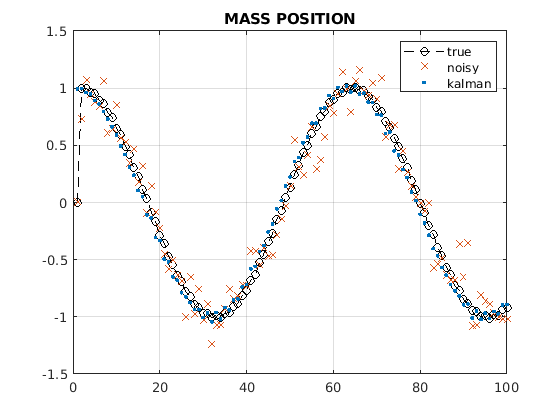

clc
close all

figure
plot(y, '--ok')
hold on
plot(y_hat, 'x', 'color', orange, 'LineWidth', 1)
plot(x_til(:,1), '.', 'color', blue, 'LineWidth', 2)
grid on
legend('true', 'noisy', 'kalman')
title('MASS POSITION')

## PROPAGATION OF STATES GAUSSIAN DISTRIBUTIONS

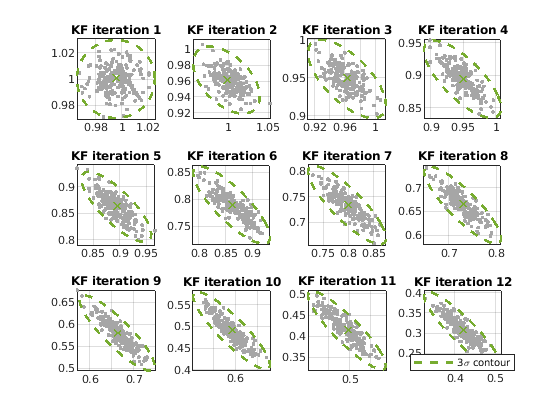

figure

for i=1:1:12

    mu = x_til(i , :)';
    P = reshape(P_til(i , :), n , n);

    xy = sigmaEllipse2D(mu, P);
    mu_r = ones (2*N, n) .* mu';
    xrand =  mvnrnd(mu_r, P)';

    subplot(3, 4, i )
    plot ( xrand(1, :), xrand(2, :), '.', 'Color', grey);
    hold on
    h1 = plot ( xy(1, :), xy(2, :),  '--', 'Color', green, 'LineWidth', 2);
    plot (mu(1), mu(2), 'x', 'Color', h1.Color, 'LineWidth', 2);
    grid on
    axis equal
    t1 = sprintf("KF iteration %d", i);
    title(t1)
end
  legend([h1], '3\sigma contour', 'Location','best')

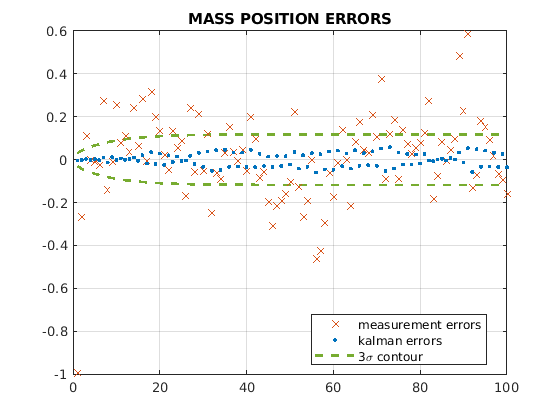

% Standard deviation * 3 vector from Kalman filter a posteriori covariance matrix
sig3_v = abs(P_til(:, 1:2:end).^(0.5)) .* 3; %  Taking only diagonal elements from Pp

figure
p3=plot(sig3_v(:, 1), '--', 'Color', green, 'LineWidth', 2);
hold on
plot(-sig3_v(:, 1), '--', 'color', green, 'LineWidth', 2);
p1=plot(y_hat-x(:,1), 'x', 'color', orange, 'LineWidth', 2, 'LineWidth', 1);
p2=plot(x_til(:,1)-x(:,1), '.', 'color', blue, 'LineWidth', 2);
grid on
legend([p1 p2 p3], 'measurement errors', 'kalman errors', '3\sigma contour', 'Location', 'best')
title('MASS POSITION ERRORS')